Cathy Zhuang

BIOL 450 Dr. Nemenman

23 April 2022

# Assignment 11: Hopfield Networks

### Question 1

Train a network of about 50 neurons with 2-3 random memories using `Training()`. Use `Recall()` to show that initial states close to one of the imprinted memories (a memory with a few neurons flipped) results in an exact recall of one of the memories.

q1 = RunProp(3, 1);
disp(q1);

     1



We see that our output of 1 means that our final output from the initial condition matches the memory 100%. See below for the coding that goes into this function.

### Question 2

Explore how the recall precision depends on the number of stored memories. That is, repeat the previous sub-problem for larger M and for a few different random realizations of the set of memories and of initial conditions for each M. Plot the fraction of times when recall results exactly in one of the stored memories as a function of M.

I will flip 5 memories for M number of memories and see when we get perfect recall. 

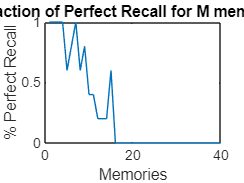

mem1 = zeros(5,1);    % for 1 memory
for i = 1:5
    mem1(i) = RunProp(1,1);
end
prop_mem(1) = sum(mem1)/5;

mem2 = zeros(5,1);    % for 2 memories
for i = 1:5
    mem2(i) = RunProp(2,1);
end
prop_mem(2) = sum(mem2)/5;

mem3 = zeros(5,1);    % for 3 memories
for i = 1:5
    mem3(i) = RunProp(3,1);
end
prop_mem(3) = sum(mem3)/5;

mem4 = zeros(5,1);    % for 4 memories
for i = 1:5
    mem4(i) = RunProp(4,1);
end
prop_mem(4) = sum(mem4)/5;

for i = 5:40         % for 5+ memories
    prop_mem(i) = RunProp(i, 5);
end

plot(prop_mem)
title('Fraction of Perfect Recall for M memories')
xlabel('Memories')
ylabel('% Perfect Recall')

It seems that as M increases, the fraction of perfect recall decreases. Thus, as we have more and more memories, we are less likely to recall results that are exactly in one of the stored memories.

### Functions

Function 1: `Recall()`. Takes weighted matrix $J_{\textrm{ij}}$ , initial condition si(0), and T iterations. Executes the deterministic dynamics prescribed in the 1982 Hopfield paper. 

function[si] = Recall(weighted, si, T)
    for i = 1:T
       si = sign(si * weighted);    % multiply weighted matrix by initial condition, and take the sign
    end
end

Function 2:  `Training()`. Takes a matrix of $M$ memories $\sigma_i^{\mu } \;$ and forms the weighted matrix $J_{\textrm{ij}}$.

Each row of the matrix is a memory.

function[J] = Training(M)
    J = zeros(size(M,2), size(M,2));      % create empty weighted matrix
    
    ind_weight = cell(size(M,1), 1);      % create individual matrices for each memory
    for i = 1:size(M,1)
        row = M(i,:);
        transpose = row.';
        ind_weight{i} = transpose * row;  % multiply the row's transpose by the row
    end
    
    for i = 1:length(ind_weight)          % summate all the individual weighted matrices
        J = J + ind_weight{i};
    end
    
    J = J - diag(diag(J));                % remove diagonal values
    
end

Function 3: RunProp(). Creates a matrix of 50 neurons and X memories, calculates the proportion of perfect recall for Y initial conditions. Initial conditions are created by flipping 5 neuron values in a memory. 

function[proportion_recall] = RunProp(X, Y) 
    pop = [-1 1]; % values of the memories

    % create a matrix with X memories and 50 neurons
    bigM = zeros(X,50);
    for i=1:X
        for j = 1:50
            bigM(i,j)= randsample(pop, 1);
        end
    end
    
    % create weighted matrix
    bigweighted = Training(bigM);
    
    % for Y memories, flip 5 random values each
    bigM2 = bigM;
    loc = randperm(50, 5);
    for i = 1:Y
        for j = 1:length(loc)
            bigM2(i, loc(j)) = -bigM2(i, loc(j));
        end
    end
    
    % run initial conditions, T = 1000
    bigfinal = zeros(Y,50);
    for i = 1:Y
        bigfinal(i,:) = Recall(bigweighted, bigM2(i,:), 1000);
    end
    
    % check to see how many match up
    matches = zeros(Y,1);
    for i = 1:Y
        matches(i,:) = isequal(bigfinal(i,:), bigM(i,:));
    end
    proportion_recall = sum(matches)/Y;
end